# 適応アルゴリズム比較

所望信号を音声で実行

## 基本

%clear;
%load('voice.mat')
fleng     = 60;     %タップ数
fsize     = length(data1);    %フレームサイズ

plotf = 0;

## LMSフィルタの設計

lmsfilt = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',0.0001);

## NLMSフィルタの設計

nlmsfilt = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',0.5);

## APフィルタの設計

po = 2;    %次元数
apfilt = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',0.5 ,'ProjectionOrder', po);

## RLSフィルタの設計

FF = 0.98;  
rlsfilt = dsp.RLSFilter(fleng, 'ForgettingFactor', FF);

## ノイズの生成

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
pinkn = Hp();
if plotf == 1
    plot(pinkn);
end
Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
whiten = Hw();
if plotf == 1
    plot(whiten);
end
Hb = dsp.ColoredNoise('Color','brown','SamplesPerFrame',fsize);
brownn = Hb();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

sinewave = dsp.SineWave('Frequency',0.01, ...
    'SampleRate',1,'SamplesPerFrame',fsize);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','LMS');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','NLMS');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','AP');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','RLS');
TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

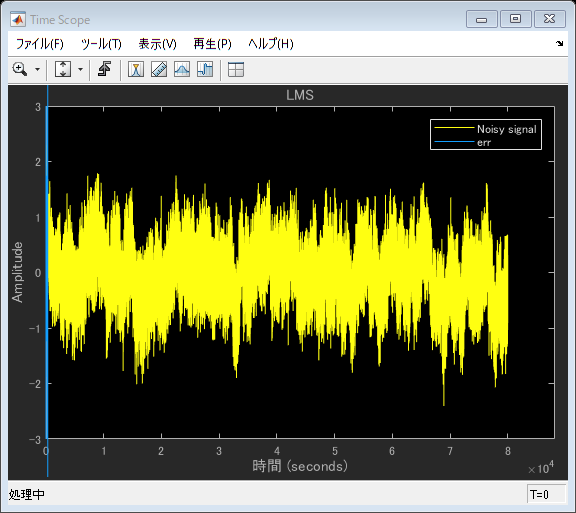

d = Hb();
s = data1;
dk = firfilt(d);
x = dk + s;
tic;
[y1,e1,wl] = lmsfilt(d,x);
t1 = toc;
TS1([x,e1]);

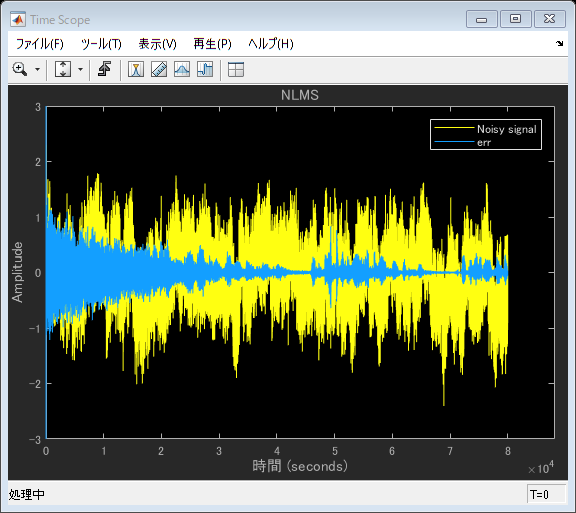

tic;
[y2,e2,wnl] = nlmsfilt(d,x);
t2 = toc;
TS2([x,e2]);

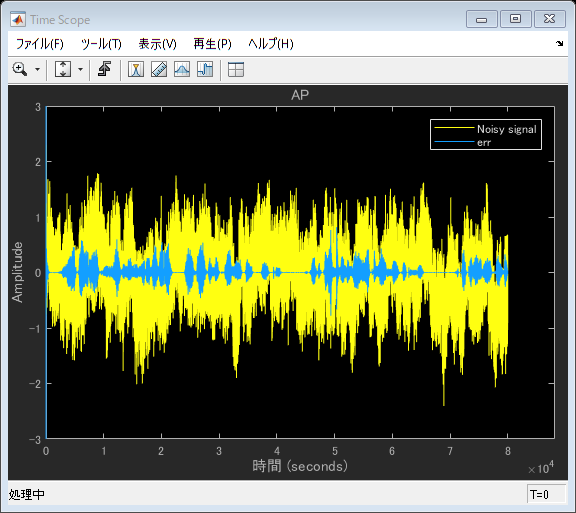

tic
[y3,e3] = apfilt(d,x);
t3 = toc;
TS3([x,e3]);

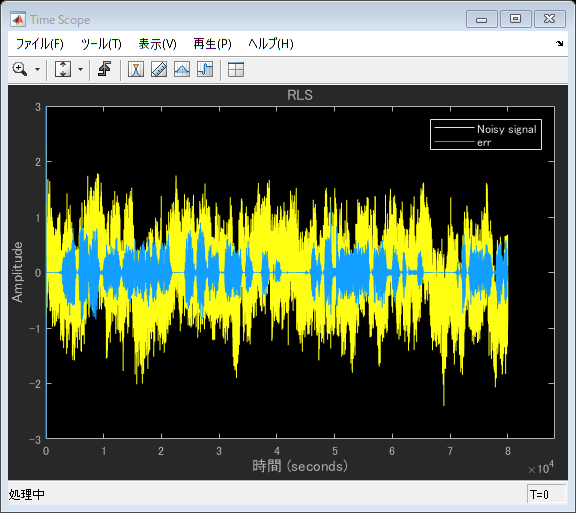

tic
[y4,e4] = rlsfilt(d,x);
t4 = toc;
TS4([x,e4]);